## Beale function $f\left(x\right)={\left(1\ldotp 5-x+\mathrm{xy}\right)}^2 +{\left(2\ldotp 25-x+{\mathrm{xy}}^2 \right)}^2 +{\left(2\ldotp 625-x+{\mathrm{xy}}^3 \right)}^2$ with a minimum $\left(3\ldotp 0,0\ldotp 5\right)$.

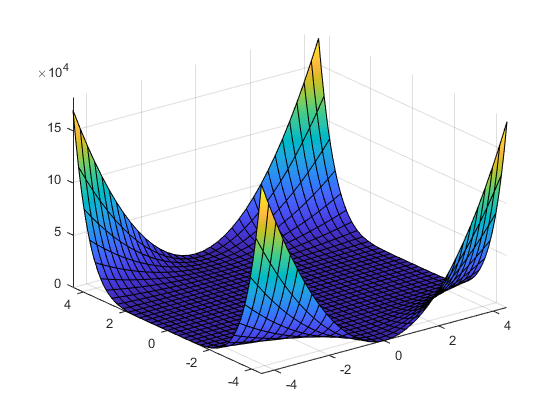

f_1= @(x) (1.5-x(1)+x(1)*x(2))^2 + (2.25-x(1)+x(1)*(x(2)^2))^2 + (2.625-x(1)+x(1)*(x(2)^3))^2;
nvars=2;
lb=[-4.5,-4.5];
ub=[4.5,4.5];

%plot
fsurf(@(x,y)(1.5-x+x*y)^2+(2.25-x+x*y^2)^2+(2.625-x+x*y^3)^2,[-4.5 4.5 -4.5 4.5])

%%ParticleSwarm%%
options = optimoptions('particleswarm','SwarmSize',100);
tic
[x,fval,exitflag,output]=particleswarm(f_1,nvars,lb,ub)

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x =     3.0000    0.5000


fval = 1.3758e-10

exitflag = 1

output = struct with fields:
      rngstate: [1×1 struct]
    iterations: 59
     funccount: 1200
       message: 'Optimization ended: relative change in the objective value ↵over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.'


toc

Elapsed time is 0.109920 seconds.


By running the algorithm multiple times, it is noticeable that by varying the number of particles, the global minimum remains essentially unchanged, at least up to the third decimal place, as does the execution time. However, the number of iterations changes, and, depending on the number of particles, it stays within a range of 40-70 iterations.

%%PatternSearch%%
options = optimoptions('patternsearch','MaxIterations',500);
x0=[2.8,0.3];
tic
[x,fval,exitflag,output]=patternsearch(f_1,x0,[],[],[],[],lb,ub,[],options)

Optimization terminated: mesh size less than options.MeshTolerance.


x =     2.9999    0.5000


fval = 7.9234e-10

exitflag = 1

output = struct with fields:
         function: @(x)(1.5-x(1)+x(1)*x(2))^2+(2.25-x(1)+x(1)*(x(2)^2))^2+(2.625-x(1)+x(1)*(x(2)^3))^2
      problemtype: 'boundconstraints'
       pollmethod: 'gpspositivebasis2n'
    maxconstraint: 0
     searchmethod: []
       iterations: 252
        funccount: 701
         meshsize: 9.5367e-07
         rngstate: [1×1 struct]
          message: 'Optimization terminated: mesh size less than options.MeshTolerance.'


toc

Elapsed time is 0.368739 seconds.


*Pattern Search* typically returns the global minimum value in 30 iterations. In particular, it is observed that when the starting point x0� is very close to the minimum point, the number of iterations increases significantly (for example, with x0 = (2.8,0.3) the number of iterations is 252), along with the execution time (increasing from one-tenth of a second to three-tenths of a second). This is because the algorithm explores a mesh of points defined based on a sufficiently rich set of directions to ensure that a descent direction is found, if one exists, and thus, starting too close to the global minimum makes it harder to find that direction.

%%FminSearch%%
x0=[0.7,2.8];
options = optimset('MaxFunEvals', 1000,'MaxIter', 1000);
tic
[x,fval,exitflag,output] = fminsearch(f_1,x0, options)

x =     3.0000    0.5000


fval = 2.8444e-10

exitflag = 1

output = struct with fields:
    iterations: 57
     funcCount: 108
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


toc

Elapsed time is 0.054102 seconds.


*Fmin Search*, unlike *Pattern Search*, when the starting point is far from the global minimum being sought, requires an increasing number of iterations and function evaluations. The execution time remains unchanged regardless of the starting point x0�.

%%Genetic algorithms%%
optionsga= optimoptions('ga', 'MaxGenerations', 500);
tic
[x,fval,exitflag,output] = ga(f_1, nvars, [],[],[],[],lb, ub, [],optionsga)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =     3.0010    0.5002


fval = 1.7971e-07

exitflag = 1

output = struct with fields:
      problemtype: 'boundconstraints'
         rngstate: [1×1 struct]
      generations: 66
        funccount: 3350
          message: 'Optimization terminated: average change in the fitness value less than options.FunctionTolerance.'
    maxconstraint: 0


toc

Elapsed time is 0.297418 seconds.


clc

It is observed that when the starting point is sufficiently close to the minimum, the fastest and most efficient minimum search algorithm is *Fmin Search*. However, if the position of the minimum point is unknown, the best algorithm, in terms of number of iterations and execution time, is *Particle Swarm*.

## **Rosenbrock function** constrained to a disk $f\left(x,y\right)={\left(1-x\right)}^2 +100{\left(y-x^2 \right)}^2$ with minimum$\left(1,1\right)$.

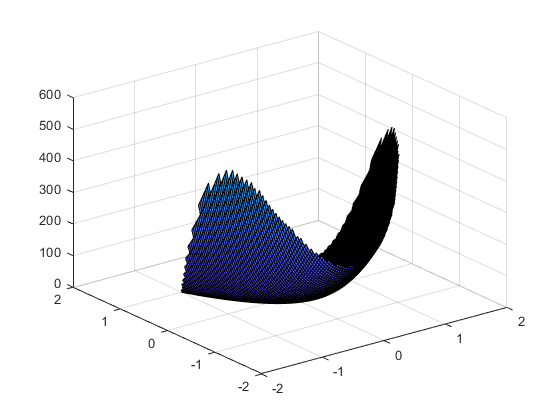

f_2=@(x) (1-x(1))^2 + 100*(x(2)-x(1)^2)^2;
nvars=2;
lb=[-1.5,-1.5];
ub=[1.5,1.5];

%plot
[xx,yy] = meshgrid(linspace(-1.5,1.5,100));
ff=(1-xx).^2+100*(yy-xx.^2).^2;
keepind = (xx.^2 + yy.^2) <= 2;
xx(~keepind) = NaN;
yy(~keepind) = NaN;
surf(xx,yy,ff);

%%PatternSearch%%
options = optimoptions('patternsearch','MaxIterations',500);
x0=[-1.5,-1.5];
tic
[x,fval,exitflag,output]=patternsearch(f_2,x0,[],[],[],[],lb,ub,@ellipsetilt,options)

Maximum number of function evaluations exceeded: increase options.MaxFunctionEvaluations.


x =     0.9397    0.8829


fval = 0.0036

exitflag = 0

output = struct with fields:
         function: @(x)(1-x(1))^2+100*(x(2)-x(1)^2)^2
      problemtype: 'nonlinearconstr'
       pollmethod: 'gpspositivebasis2n'
    maxconstraint: 0
     searchmethod: []
       iterations: 3
        funccount: 4000
         meshsize: 1.0000e-07
         rngstate: [1×1 struct]
          message: 'Maximum number of function evaluations exceeded: increase options.MaxFunctionEvaluations.'


toc

Elapsed time is 2.734157 seconds.


As for the execution of *Pattern Search*, no significant changes are observed in the execution time or the number of iterations as the starting point x0 varies.

%%FminSearch%%
x0=[-1.5,-1.5];
tic
[x,fval,exitflag,output] = fminsearch(f_2,x0)

x =     1.0000    1.0000


fval = 6.5075e-10

exitflag = 1

output = struct with fields:
    iterations: 54
     funcCount: 105
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


toc

Elapsed time is 0.048308 seconds.


Even with *Fmin Search*, no significant changes are observed in the minimum found or in the execution time as the starting point varies, except for a slight increase in the number of iterations required when the point x0 is placed on the boundary of the function’s domain.

%%Algoritmi Genetici%
optionsga= optimoptions('ga', 'MaxGenerations', 500);
tic
[x,fval,exitflag,output] = ga(f_2, nvars, [],[],[],[],lb, ub,@ellipsetilt,optionsga)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


x =     0.9948    0.9896


fval = 2.7582e-05

exitflag = 1

output = struct with fields:
      problemtype: 'nonlinearconstr'
         rngstate: [1×1 struct]
      generations: 5
        funccount: 13050
          message: 'Optimization terminated: average change in the fitness value less than options.FunctionTolerance↵ and constraint violation is less than options.ConstraintTolerance.'
    maxconstraint: 0


toc

Elapsed time is 2.637145 seconds.


clc

It can be concluded that the algorithm that performs best in terms of execution time and the minimum found is *Fmin Search*.

## Gomez and Levy function (modified) $f\left(x,y\right)=4x^2 -2\ldotp 1x^4 +\frac{1}{3}x^6 +\textrm{xy}-4y^2 +4y^4$ with minimum$\left(0\ldotp 08984201,-0\ldotp 71226564\right)$.

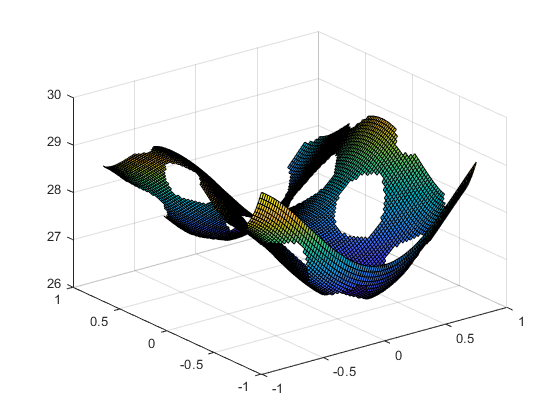

f_3= @(x)4*x(1)^2-2.1*x(1)^4+(1/3)*x(1)^6+x(1)*x(2)-4*x(2)^2+4*x(2)^4;
nvars=2;
A = [];
b = [];
Aeq = [];
beq = [];
lb = [-1,-1];
ub = [0.75,1];
x0 = [-0.75,0.5];

[xx,yy] = meshgrid(linspace(-1,0.75,100));
ff=4*xx.^2-2.1*xx.^4+(1/3)*xx.^6+xx*yy-4*yy.^2+4*yy.^4;
keepind = (-sin(4*pi.*xx) + 2*(sin(2*pi.*yy)).^2) <= 1.5;
xx(~keepind) = NaN;
yy(~keepind) = NaN;
surf(xx,yy,ff);

%%PatternSearch%%
nonlcon = @ellipsetilt3; %si veda la fine dello script
x0=[0.3,0.1];
tic
x = patternsearch(f_3,x0,A,b,Aeq,beq,lb,ub,nonlcon)

Optimization terminated: mesh size less than options.MeshTolerance
 and constraint violation is less than options.ConstraintTolerance.


x =     0.0898   -0.7127


toc

Elapsed time is 0.262784 seconds.


For *Pattern Search*, it is observed that when the starting point x0 is far from the global minimum, the latter does not coincide with the minimum found by the algorithm. The execution time shows no significant changes.

%Genetics algorithms%%
rng default % For reproducibility
nonlcon = @ellipsecons;
tic
x = ga(f_3,nvars,A,b,Aeq,beq,lb,ub,nonlcon)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


x =     0.0898   -0.7127


toc

Elapsed time is 2.631659 seconds.


clc

It can be observed that *Pattern Search*, when the starting point x0� is sufficiently close to the global minimum, has a significantly lower execution time compared to genetic algorithms.

## Easom function $f\left(x\right)=-\cos \left(x\right)\cos \left(y\right)e^{-\left\lbrack {\left(x-\pi \right)}^2 +{\left(y-\pi \right)}^2 \right\rbrack }$ with global minimum$\left(\pi ,\pi \right)$.

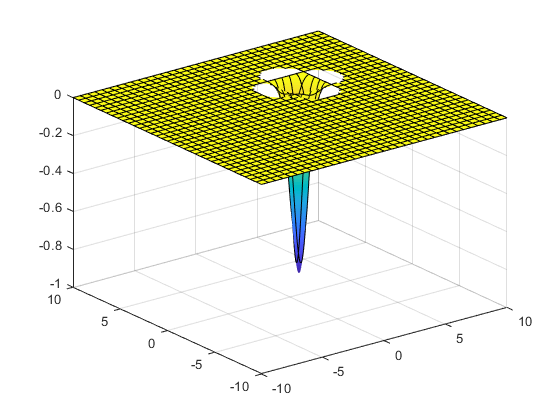

f_4 = @(x)-cos(x(1))*cos(x(2))*exp(-(((x(1)-pi)^2+(x(2)-pi)^2)));
nvars=2;
A=[];
b=[];
Aeq=[];
beq=[];
lb=[-100,-100];
ub=[100,100];
nonlcon=[];

%plot
fsurf(@(x,y)(-cos(x)*cos(y)*exp(-(((x-pi)^2+(y-pi)^2)))),[-10 10 -10 10])

%%ParticleSwarm%%
rng default
options = optimoptions('particleswarm','SwarmSize',200);
tic
[x,fval,exitflag,output] = particleswarm(f_4,nvars,lb,ub)

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x =     3.1416    3.1416


fval = -1.0000

exitflag = 1

output = struct with fields:
      rngstate: [1×1 struct]
    iterations: 80
     funccount: 1620
       message: 'Optimization ended: relative change in the objective value ↵over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.'


toc

Elapsed time is 0.114980 seconds.


Particle Swarm retituisce il corretto valore del global minimum in 80 iterazioni, con tempo di esecuzione sostanzialmente invariato, indipendentemente dal numero di particelle.

%%PatternSearch%%
options = optimoptions('patternsearch','MeshTolerance',1e-4);
x0=[-10,10];
tic
[x,fval,exitflag,output] = patternsearch(f_4,x0,A,b,Aeq,beq,lb,ub,nonlcon,options)

Optimization terminated: mesh size less than options.MeshTolerance.


x =     3.1406    3.1406


fval = -1.0000

exitflag = 1

output = struct with fields:
         function: @(x)-cos(x(1))*cos(x(2))*exp(-(((x(1)-pi)^2+(x(2)-pi)^2)))
      problemtype: 'boundconstraints'
       pollmethod: 'gpspositivebasis2n'
    maxconstraint: 0
     searchmethod: []
       iterations: 44
        funccount: 149
         meshsize: 6.1035e-05
         rngstate: [1×1 struct]
          message: 'Optimization terminated: mesh size less than options.MeshTolerance.'


toc

Elapsed time is 0.107929 seconds.


*Pattern Search* returns a value that coincides with the global minimum (in 30 iterations) if the starting point x0� is very close to the minimum point. Otherwise, it either doesn't move (for example, with x0 = (30,30)) or doesn't reach the minimum (with x0 = (1,1)), as the algorithm explores a mesh of points defined based on a sufficiently rich set of directions to ensure that a descent direction is found if one exists. Therefore, when starting far from the minimum, this direction is not found, and no movement occurs from the initial point.

%%FminSearch%% -- In the options, there is no possibility to set the interval for 
% x and y, but the algorithm still terminates
%fun=@(x)-cos(x(1))*cos(x(2))*exp(-((x(1)-pi)^2+(x(2)-pi)^2));
x0=[10,10];
tic
[x,fval,exitflag,output] = fminsearch(f_4,x0)

x =     3.1416    3.1416


fval = -1.0000

exitflag = 1

output = struct with fields:
    iterations: 41
     funcCount: 77
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


toc

Elapsed time is 0.059818 seconds.


*Fmin Searc*h returns a value that coincides with the global minimum under the same conditions as *Pattern Search* (for example, by choosing x0=(10,10))

%%Genetic algorithms%%
lb=[-100,-100];
ub=[100,100];
tic
[x,fval,exitflag,output] = ga(f_4,nvars,A,b,Aeq,beq,lb,ub)

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


x =     3.1416    3.1416


fval = -1.0000

exitflag = 1

output = struct with fields:
      problemtype: 'boundconstraints'
         rngstate: [1×1 struct]
      generations: 86
        funccount: 4350
          message: 'Optimization terminated: average change in the fitness value less than options.FunctionTolerance.'
    maxconstraint: 0


toc

Elapsed time is 0.368277 seconds.


It can be concluded that if the exact or approximate position of the global minimum is unknown, it is advisable to use genetic algorithms. Alternatively, the other two methods, when choosing an x0 close to the minimum point, are essentially equivalent